# Extract Coordinates from stl

This code is to transform stl into a mesh and list out all coordinates. The 'nodes' variable contains all coordinates that the part consists of in the STL file.

For github commits, refer to this: [https://www.mathworks.com/help/matlab/ref/matlab.git.gitrepository.commit.html](https://www.mathworks.com/help/matlab/ref/matlab.git.gitrepository.commit.html)

### Stadium STL FIle

gm = fegeometry("simple_model.stl",AllowSelfIntersections=false);

gm =   fegeometry with properties:

       NumFaces: 8
       NumEdges: 14
    NumVertices: 10
       NumCells: 1
       Vertices: [10x3 double]
           Mesh: []


model = rotate(gm,90,[0 0 0], [1 0 0]); % Rotate 90 degrees about X to align height with Z-axis
new_gm = generateMesh(model);
nodes = new_gm.Mesh.Nodes           % every column is a point coordinate

nodes =     0.0056    0.0056   -0.0549   -0.0549   -0.0054   -0.0668   -0.0054   -0.0668   -0.0000   -0.0000    0.0733    0.0733    0.0576    0.0576   -0.0499   -0.0449   -0.0398   -0.0348   -0.0297   -0.0247   -0.0196   -0.0146   -0.0095   -0.0045    0.0006    0.0056    0.0056   -0.0549   -0.0549    0.0006   -0.0045   -0.0095   -0.0146   -0.0196   -0.0247   -0.0297   -0.0348   -0.0398   -0.0449   -0.0499   -0.0054   -0.0054   -0.0103   -0.0152   -0.0201   -0.0250   -0.0299   -0.0348   -0.0396   -0.0445
    0.0111   -0.0111    0.0111   -0.0111    0.0111    0.0111   -0.0111   -0.0111   -0.0483   -0.0483   -0.0000   -0.0000    0.0298    0.0298    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0037   -0.0037   -0.0037    0.0037   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0037    0.0037    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111 

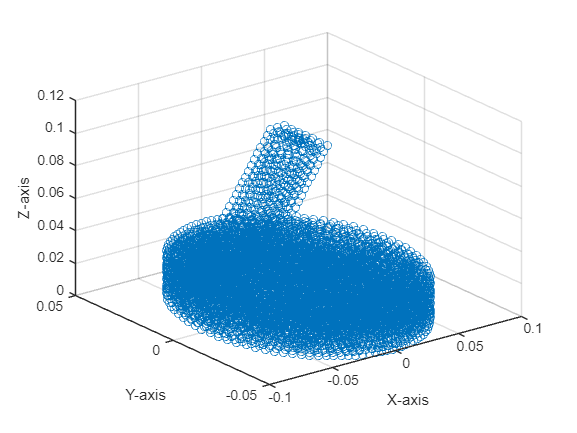

scatter3(nodes(1,:),nodes(2,:),nodes(3,:))
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% pdemesh(new_gm)

This code section gives an angle adjustment for the print bed

z_row_values = nodes(3, :);
columns_to_update = find(z_row_values >= 0.025);

if ~isempty(columns_to_update)
    for col = columns_to_update
        % Update rows 4, 5, and 6 with different value
        nodes(4:6, col) = [0;-pi/4;0];
    end
else
    disp('No columns satisfy the condition.');
end

Next we need to transform the coordinates into the print mode coordinates. This will be done by multiplying everything by -1

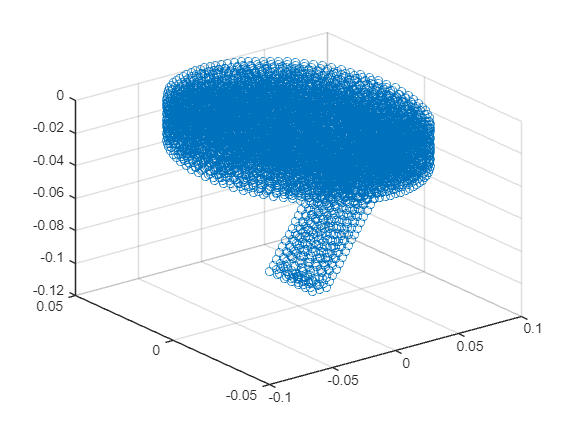


nodes(1:3,:) = nodes(1:3,:)*-1;
scatter3(nodes(1,:),nodes(2,:),nodes(3,:))

This is the unordered set of nodes:

nodes

nodes =    -0.0056   -0.0056    0.0549    0.0549    0.0054    0.0668    0.0054    0.0668    0.0000    0.0000   -0.0733   -0.0733   -0.0576   -0.0576    0.0499    0.0449    0.0398    0.0348    0.0297    0.0247    0.0196    0.0146    0.0095    0.0045   -0.0006   -0.0056   -0.0056    0.0549    0.0549   -0.0006    0.0045    0.0095    0.0146    0.0196    0.0247    0.0297    0.0348    0.0398    0.0449    0.0499    0.0054    0.0054    0.0103    0.0152    0.0201    0.0250    0.0299    0.0348    0.0396    0.0445
   -0.0111    0.0111   -0.0111    0.0111   -0.0111   -0.0111    0.0111    0.0111    0.0483    0.0483    0.0000    0.0000   -0.0298   -0.0298   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0037    0.0037    0.0037   -0.0037    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0037   -0.0037   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111 

Next is to reorder nodes based on the Z-axis 

sorted_nodes = sortrows(nodes',-3)

sorted_nodes =     0.0000    0.0483         0         0         0         0
   -0.0733    0.0000         0         0         0         0
   -0.0576   -0.0298         0         0         0         0
   -0.0510   -0.0346         0         0         0         0
   -0.0438   -0.0387         0         0         0         0
   -0.0363   -0.0419         0         0         0         0
   -0.0285   -0.0444         0         0         0         0
   -0.0205   -0.0463         0         0         0         0
   -0.0124   -0.0476         0         0         0         0
   -0.0042   -0.0482         0         0         0         0


scatter3(sorted_nodes(:,1),sorted_nodes(:,2),sorted_nodes(:,3))

Store sorted nodes into nodes variable.

nodes = sorted_nodes'

nodes =     0.0000   -0.0733   -0.0576   -0.0510   -0.0438   -0.0363   -0.0285   -0.0205   -0.0124   -0.0042    0.0040    0.0122    0.0203    0.0283    0.0361    0.0437    0.0508    0.0575    0.0634    0.0682    0.0716    0.0732    0.0727    0.0702    0.0660    0.0606    0.0543    0.0474    0.0400    0.0323    0.0244    0.0164    0.0082   -0.0721   -0.0688   -0.0638   -0.0080   -0.0160   -0.0239   -0.0317   -0.0392   -0.0465   -0.0533   -0.0596   -0.0651   -0.0694   -0.0723    0.0038   -0.0037    0.0115
    0.0483    0.0000   -0.0298   -0.0346   -0.0387   -0.0419   -0.0444   -0.0463   -0.0476   -0.0482   -0.0482   -0.0476   -0.0464   -0.0445   -0.0420   -0.0387   -0.0347   -0.0299   -0.0242   -0.0176   -0.0101   -0.0021    0.0061    0.0139    0.0209    0.0271    0.0324    0.0368    0.0404    0.0433    0.0455    0.0470    0.0479   -0.0086   -0.0166   -0.0237    0.0480    0.0471    0.0456    0.0435    0.0408    0.0373    0.0331    0.0281    0.0222    0.0154    0.0080    0.0410    0.0411 


save("simple_model.stl","nodes")

## Pipe STL

This section is for extracting nodes for the pipe object

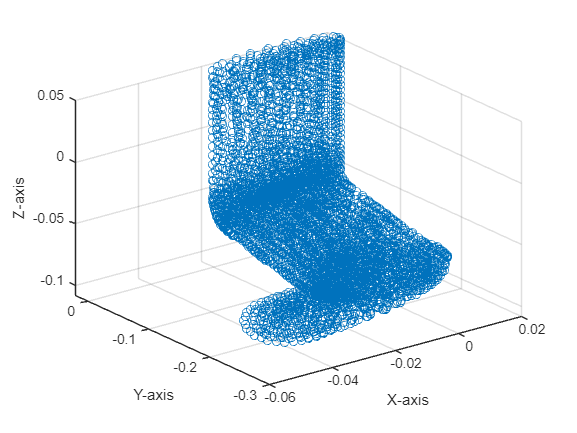

pipe_gm = fegeometry("pipe_model.stl",AllowSelfIntersections=false);
% pipe_model = rotate(pipe_gm,90,[0 0 0], [1 0 0]); % Rotate 90 degrees about X to align height with Z-axis
new_pipe_gm = generateMesh(pipe_model);
nodes_pipe = new_pipe_gm.Mesh.Nodes;

scatter3(nodes_pipe(1,:),nodes_pipe(2,:),nodes_pipe(3,:))
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

There are 3 segments that require angle changes in the pipe.

z_row_values = nodes_pipe(3, :);
columns_to_update = find((-.0878>=z_row_values) & (z_row_values>= 0.1065));
if ~isempty(columns_to_update)
    for col = columns_to_update
        % Update rows 4, 5, and 6 with different value
        nodes_pipe(4:6, col) = [-.1326;0;0];
    end
end
next_update = find((-.04896>=z_row_values) & (z_row_values>= -.0878));
if ~isempty(next_update)
    for col = next_update
        % Update rows 4, 5, and 6 with different value
        nodes_pipe(4:6, col) = [-pi/3;0;0];
    end
end
nodes_pipe  

nodes_pipe =     0.0202   -0.0135   -0.0118   -0.0043    0.0068    0.0147    0.0191    0.0185    0.0147    0.0060   -0.0185    0.0191   -0.0200   -0.0087    0.0017    0.0026    0.0052    0.0028    0.0075   -0.0157    0.0113   -0.0493   -0.0284   -0.0290    0.0094   -0.0220   -0.0049   -0.0086   -0.0123   -0.0156   -0.0184   -0.0198   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0198   -0.0198   -0.0198   -0.0176   -0.0202   -0.0193   -0.0190   -0.0190   -0.0168   -0.0126
   -0.1764   -0.1483   -0.1481   -0.1476    0.0188    0.0135   -0.0060   -0.0077   -0.0135   -0.0191   -0.0077   -0.0060   -0.0175   -0.0181   -0.0199   -0.0198   -0.0193   -0.0207   -0.0200    0.0111   -0.0039   -0.2030   -0.2367   -0.2327   -0.2054   -0.1821   -0.0205   -0.0199   -0.0197   -0.0198   -0.0190   -0.0181   -0.0235   -0.0352   -0.0479   -0.0606   -0.0733   -0.0860   -0.0987   -0.1115   -0.1242   -0.1369   -0.1481   -0.1490   -0.1770   -0.1734   -0.1659   -0.1547   -0.

nodes_pipe(1:3,:) = nodes_pipe(1:3,:)*-1;
sorted_nodes_pipe = sortrows(nodes_pipe',-3)

sorted_nodes_pipe =     0.0283    0.2129    0.1081         0         0         0
    0.0021    0.1664    0.1080         0         0         0
    0.0134    0.1991    0.1080         0         0         0
    0.0314    0.2171    0.1080         0         0         0
    0.0028    0.1729    0.1079         0         0         0
    0.0026    0.1613    0.1079         0         0         0
    0.0335    0.2138    0.1079         0         0         0
    0.0036    0.1794    0.1079         0         0         0
    0.0031    0.1562    0.1079         0         0         0
   -0.0002    0.1519    0.1078         0         0         0


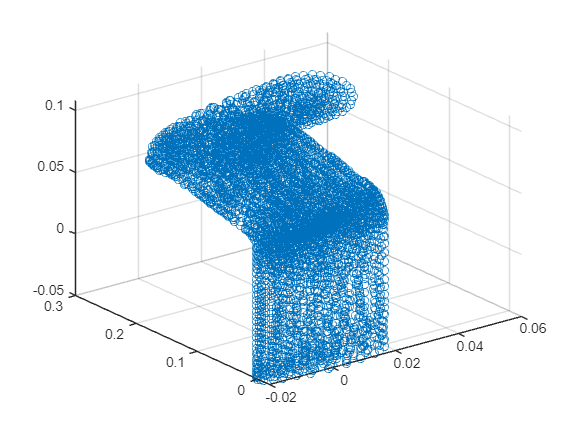

scatter3(sorted_nodes_pipe(:,1),sorted_nodes_pipe(:,2),sorted_nodes_pipe(:,3))



save("pipe_data","nodes_pipe")
